This script runs robust regression on the contrasts from CESciO

% PARAMETERS

%     - CUE

%     - EXPECT

%     - STIM

%     - STIM x cue

%     - STIM x intensity

%     - OUTCOME

contrast_name = {
    'P_VC_epoch_cue', 'V_PC_epoch_cue', 'C_PV_epoch_cue',...
    'P_VC_epoch_stim', 'V_PC_epoch_stim', 'C_PV_epoch_stim',...
    'P_VC_pmod_stimXcue', 'V_PC_pmod_stimXcue', 'C_PV_pmod_stimXcue',...
    'P_VC_pmod_stimXintensity', 'V_PC_pmod_stimXintensity', 'C_PV_pmod_stimXintensity',...
    'motor',...
    'P_simple_epoch_cue', 'V_simple_epoch_cue', 'C_simple_epoch_cue',...
    'P_simple_epoch_stim', 'V_simple_epoch_stim', 'C_simple_epoch_stim',...
    'P_simple_pmod_stimXcue', 'V_simple_pmod_stimXcue', 'C_simple_pmod_stimXcue',...
    'P_simple_pmod_stimXintensity', 'V_simple_pmod_stimXintensity', 'C_simple_pmod_stimXintensity'
};

## Parameter

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel';


## Check motor maps

% load dataset
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel';

% TODO: grab subject contrasts that match subject id in the model simulated data
% ESSENTIAL - identify full fmri participants
con_list = dir(fullfile(mount_dir, '*/con_0013.nii'));
[f,base,e] = fileparts({con_list.folder})

f = 1×63 cell array
    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel'}    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel'}    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel'}    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel'}    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel'}    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel'}    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel'}    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel'}    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel'}    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel'}    {'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/mode

base = 1×63 cell array
    {'sub-0013'}    {'sub-0014'}    {'sub-0016'}    {'sub-0026'}    {'sub-0028'}    {'sub-0030'}    {'sub-0032'}    {'sub-0033'}    {'sub-0035'}    {'sub-0036'}    {'sub-0037'}    {'sub-0038'}    {'sub-0039'}    {'sub-0041'}    {'sub-0044'}    {'sub-0047'}    {'sub-0053'}    {'sub-0056'}    {'sub-0057'}    {'sub-0060'}    {'sub-0061'}    {'sub-0062'}    {'sub-0064'}    {'sub-0066'}    {'sub-0068'}    {'sub-0069'}    {'sub-0071'}    {'sub-0073'}    {'sub-0074'}    {'sub-0075'}    {'sub-0076'}    {'sub-0077'}    {'sub-0078'}    {'sub-0080'}    {'sub-0084'}    {'sub-0085'}    {'sub-0086'}    {'sub-0088'}    {'sub-0089'}    {'sub-0093'}    {'sub-0095'}    {'sub-0099'}    {'sub-0101'}    {'sub-0104'}    {'sub-0106'}    {'sub-0107'}    {'sub-0109'}    {'sub-0111'}    {'sub-0115'}    {'sub-0116'}    {'sub-0118'}    {'sub-0119'}    {'sub-0120'}    {'sub-0123'}    {'sub-0124'}    {'sub-0126'}    {'sub-0127'}    {'sub-0128'}    {'sub-0129'}    {'sub-0130'}    {'sub-0131'} 

e = 1×63 cell array
    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}


sublist= base';

spm('Defaults','fMRI')
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 25158924 bytes
Loading image number:    63
Elapsed time is 2.064623 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6079915  Bit rate: 22.54 bits


con_data_obj.metadata_table.sub = sublist;
% load behavioral data and attach to dataobject




## RL w fit and pain stim

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel';

% behavioral: 
RLfitfname = '/Users/h/Documents/projects_local/cue_expectancy/data/RL/modelfit_jepma_0525/par_mdl2_pain.csv'

RLfitfname = '/Users/h/Documents/projects_local/cue_expectancy/data/RL/modelfit_jepma_0525/par_mdl2_pain.csv'

RLfit = readtable(RLfitfname);
keys = cell(size(RLfit.subj_num_new_pain));
for i = 1:numel(RLfit.subj_num_new_pain)
    keys{i} = sprintf('sub-%04d', RLfit.subj_num_new_pain(i));
end
RLfit.sub = keys;
overlap = intersect(con_data_obj.metadata_table.sub, RLfit.sub);% >> 36 subjects
% load subjects that overlap with RL fitted data
con_list = []


con_list =

     []



for sub = 1:length(overlap)
    matchingFiles = dir(fullfile(mount_dir,overlap{sub}, 'con_0017.nii'));
    con_list = [con_list; fullfile(matchingFiles.folder, matchingFiles.name )]; % P_simple_epoch_stim
end

con_data_obj = fmri_data(con_list);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 14376528 bytes
Loading image number:    36
Elapsed time is 1.144312 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 3525716  Bit rate: 21.75 bits


con_data_obj.metadata_table.sub =overlap; %sublist;

% find intersection
overlap = intersect(con_data_obj.metadata_table.sub, RLfit.sub);
% add alphas to fmri_data object
con_data_obj.X = RLfit.alpha_i(ismember(RLfit.sub, overlap))

con_data_obj =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [36×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [36×1 table]
                   dat: [99837×36 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [36×12 char]
              fullpath: [36×105 char]
           files_exist: [36×1 logical]
  

SPM12: spm_check_registration (v7759)              19:50:38 - 08/06/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


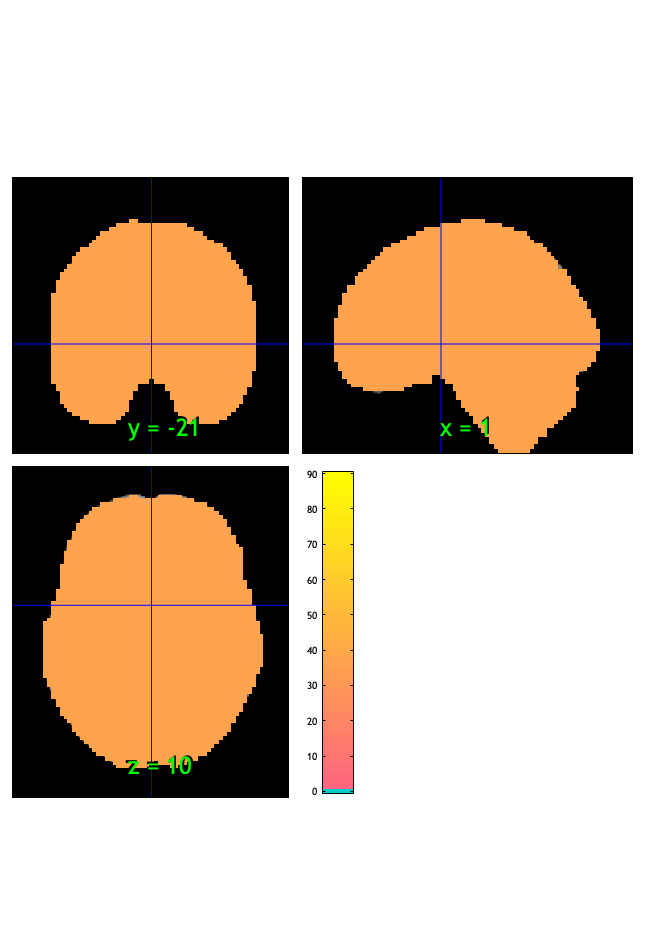

ans = 1×1 cell array
    {1×1 region}



%% check data coverage
m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display


%% run ols
out = regress(con_data_obj, .05, 'unc', 'nodisplay');

Analysis: 
----------------------------------
Design matrix warnings:
----------------------------------
No intercept detected, adding intercept to last column of design matrix                                                     
Warning!!!  Some observations have high leverage values relative to others, regression may be unstable. abs(z(leverage)) > 3
Warning!!!  Too few variable names entered, less than size(X, 2). Names may be inaccurate.                                  
 
______________________________________________________
Running regression: 99837 voxels. Design:  36 obs,   2 regressors, intercept is last

Predicting exogenous variable(s) in dat.X using brain data as predictors, mass univariate
Running in OLS Mode
Model run in 0 minutes and 0.14 seconds

Creating beta and t images, thresholding t images
___________________________________________________

t = threshold(out.t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.000000

Image   1
  0 contig. clusters, sizes     to    
Positive effect:   0 voxels, min p-value: 0.00000525
Negative effect:   0 voxels, min p-value: 0.00001179
Image   2 FDR q < 0.050 threshold is 0.017891

Image   2
  0 contig. clusters, sizes     to    
Positive effect: 32009 voxels, min p-value: 0.00000000
Negative effect: 3719 voxels, min p-value: 0.00000035


Grouping contiguous voxels:  60 regions
    48



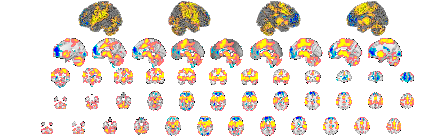

o2 = canlab_results_fmridisplay(get_wh_image(t, 2), 'montagetype', 'full', 'noverbose');

out_parcel = robfit_parcelwise(con_data_obj); %'names', ## );

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


Error using load
Unable to find file or directory 'CANlab_combined_atlas_object_2018_2mm.mat'.

Error in load_atlas>load_atlas_from_file (line 201)
    atlas_obj = load(savefile, varname);

Error in load_atlas (line 175)
atlas_ob

% Adjust for global intensity and global components and re-run:
imgs2 = con_data_obj.rescale('l2norm_images');
OUT = robfit_parcelwise(imgs2);
%
% Run adding global WM and CSF signal covariates:
OUT = robfit_parcelwise(imgs2, 'csf_wm_covs');
%
% run with global covariates and removing outliers based on Mahalanobis distance:
OUT = robfit_parcelwise(imgs2, 'csf_wm_covs', 'remove_outliers');


# vicarious

## RL w fit and vicarious stim

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel';

% behavioral: 
RLfitfname = '/Users/h/Documents/projects_local/cue_expectancy/data/RL/modelfit_jepma_0525/par_mdl2_vic.csv'

RLfitfname = '/Users/h/Documents/projects_local/cue_expectancy/data/RL/modelfit_jepma_0525/par_mdl2_vic.csv'

RLfit = readtable(RLfitfname);
keys = cell(size(RLfit.subj_num_new_vicarious));
for i = 1:numel(RLfit.subj_num_new_vicarious)
    keys{i} = sprintf('sub-%04d', RLfit.subj_num_new_vicarious(i));
end
RLfit.sub = keys;
overlap = intersect(con_data_obj.metadata_table.sub, RLfit.sub);% >> 36 subjects
% load subjects that overlap with RL fitted data
con_list = []


con_list =

     []



for sub = 1:length(overlap)
    matchingFiles = dir(fullfile(mount_dir,overlap{sub}, 'con_0018.nii'));
    con_list = [con_list; fullfile(matchingFiles.folder, matchingFiles.name )]; % P_simple_epoch_stim
end

con_data_obj = fmri_data(con_list);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 12379788 bytes
Loading image number:    31
Elapsed time is 0.914754 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 3045913  Bit rate: 21.54 bits


con_data_obj.metadata_table.sub =overlap; %sublist;

% find intersection
overlap = intersect(con_data_obj.metadata_table.sub, RLfit.sub);
% add alphas to fmri_data object
con_data_obj.X = RLfit.alpha_i(ismember(RLfit.sub, overlap))

con_data_obj =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [31×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [31×1 table]
                   dat: [99837×31 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [31×12 char]
              fullpath: [31×105 char]
           files_exist: [31×1 logical]
  


%% check data coverage
m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              19:54:45 - 08/06/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}



%% run ols
out = regress(con_data_obj, .05, 'unc', 'nodisplay');

Analysis: 
----------------------------------
Design matrix warnings:
----------------------------------
No intercept detected, adding intercept to last column of design matrix                                                     
Warning!!!  Some observations have high leverage values relative to others, regression may be unstable. abs(z(leverage)) > 3
Warning!!!  Too few variable names entered, less than size(X, 2). Names may be inaccurate.                                  
 
______________________________________________________
Running regression: 99837 voxels. Design:  31 obs,   2 regressors, intercept is last

Predicting exogenous variable(s) in dat.X using brain data as predictors, mass univariate
Running in OLS Mode
Model run in 0 minutes and 0.14 seconds

Creating beta and t images, thresholding t images
___________________________________________________

t = threshold(out.t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.000426

Image   1
 83 contig. clusters, sizes   1 to  70
Positive effect: 832 voxels, min p-value: 0.00000041
Negative effect:  18 voxels, min p-value: 0.00000007
Image   2 FDR q < 0.050 threshold is 0.027675

Image   2
 83 contig. clusters, sizes   1 to  70
Positive effect: 18096 voxels, min p-value: 0.00000000
Negative effect: 37172 voxels, min p-value: 0.00000000


Grouping contiguous voxels:  25 regions
    48



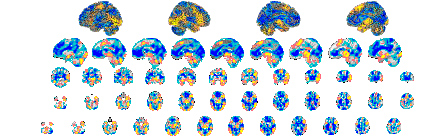

o2 = canlab_results_fmridisplay(get_wh_image(t, 2), 'montagetype', 'full', 'noverbose');

out_parcel = robfit_parcelwise(con_data_obj); %'names', ## );


# cognitive

## RL w fit and cognitive stim

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESciO/1stLevel';

% behavioral: 
RLfitfname = '/Users/h/Documents/projects_local/cue_expectancy/data/RL/modelfit_jepma_0525/par_mdl2_cog.csv'

RLfitfname = '/Users/h/Documents/projects_local/cue_expectancy/data/RL/modelfit_jepma_0525/par_mdl2_cog.csv'

RLfit = readtable(RLfitfname);
keys = cell(size(RLfit.subj_num_new_cognitive));
for i = 1:numel(RLfit.subj_num_new_cognitive)
    keys{i} = sprintf('sub-%04d', RLfit.subj_num_new_cognitive(i));
end
RLfit.sub = keys;
overlap = intersect(con_data_obj.metadata_table.sub, RLfit.sub);% >> 36 subjects
% load subjects that overlap with RL fitted data
con_list = []


con_list =

     []



for sub = 1:length(overlap)
    matchingFiles = dir(fullfile(mount_dir,overlap{sub}, 'con_0019.nii'));
    con_list = [con_list; fullfile(matchingFiles.folder, matchingFiles.name )]; % P_simple_epoch_stim
end

con_data_obj = fmri_data(con_list);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 12379788 bytes
Loading image number:    31
Elapsed time is 1.345310 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 3045712  Bit rate: 21.54 bits


con_data_obj.metadata_table.sub =overlap; %sublist;

% find intersection
overlap = intersect(con_data_obj.metadata_table.sub, RLfit.sub);
% add alphas to fmri_data object
con_data_obj.X = RLfit.alpha_i(ismember(RLfit.sub, overlap))

con_data_obj =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [31×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [31×1 table]
                   dat: [99837×31 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [31×12 char]
              fullpath: [31×105 char]
           files_exist: [31×1 logical]
  

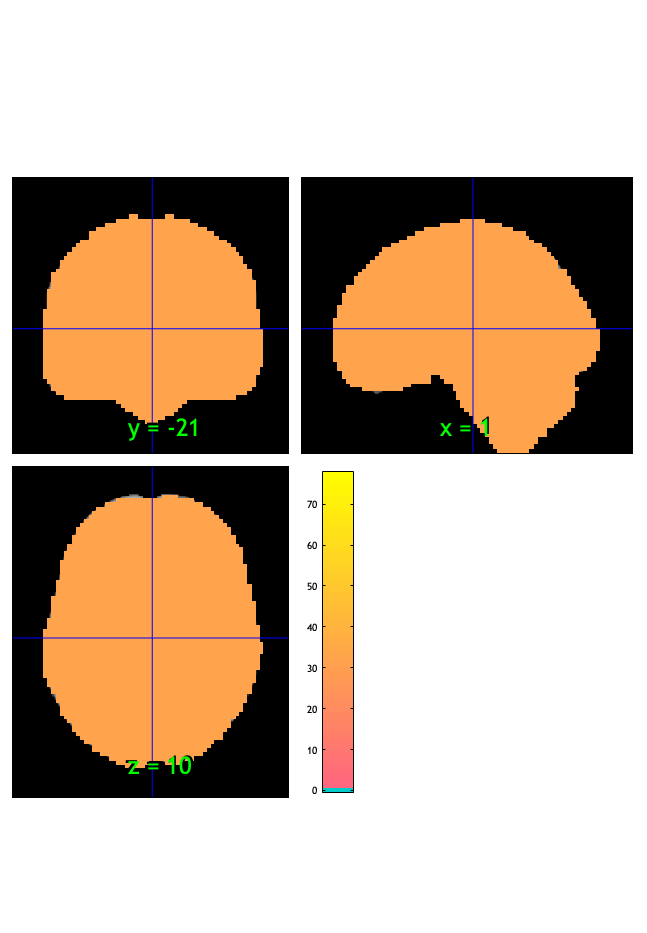

SPM12: spm_check_registration (v7759)              19:54:58 - 08/06/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


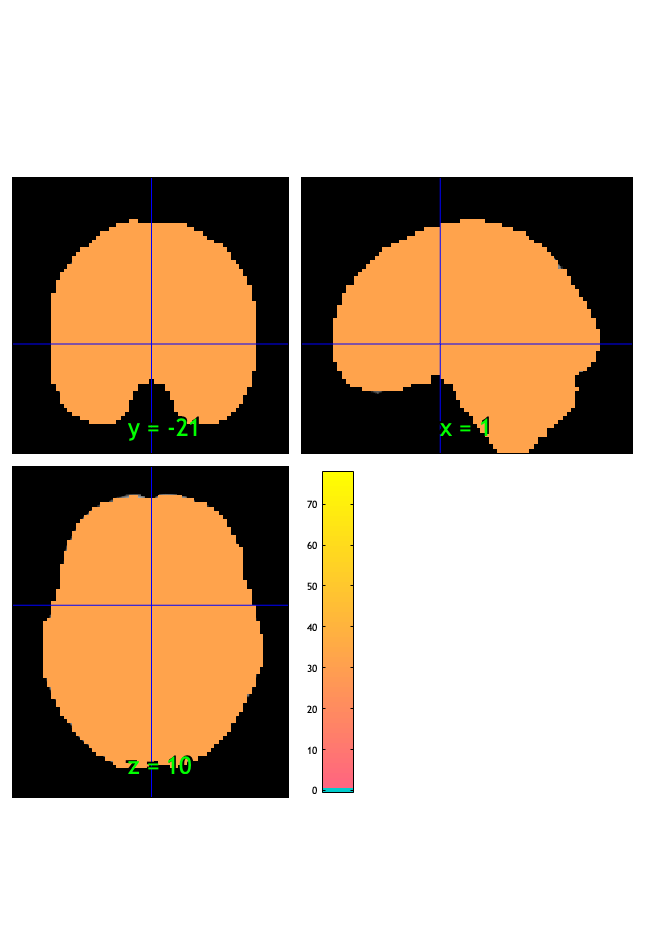

ans = 1×1 cell array
    {1×1 region}



%% check data coverage
m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display


%% run ols
out = regress(con_data_obj, .05, 'unc', 'nodisplay');

Analysis: 
----------------------------------
Design matrix warnings:
----------------------------------
No intercept detected, adding intercept to last column of design matrix                                                     
Warning!!!  Some observations have high leverage values relative to others, regression may be unstable. abs(z(leverage)) > 3
Warning!!!  Too few variable names entered, less than size(X, 2). Names may be inaccurate.                                  
 
______________________________________________________
Running regression: 99837 voxels. Design:  31 obs,   2 regressors, intercept is last

Predicting exogenous variable(s) in dat.X using brain data as predictors, mass univariate
Running in OLS Mode
Model run in 0 minutes and 0.16 seconds

Creating beta and t images, thresholding t images
___________________________________________________

t = threshold(out.t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.000000

Image   1
  0 contig. clusters, sizes     to    
Positive effect:   0 voxels, min p-value: 0.00000060
Negative effect:   0 voxels, min p-value: 0.00008454
Image   2 FDR q < 0.050 threshold is 0.035675

Image   2
  0 contig. clusters, sizes     to    
Positive effect: 41193 voxels, min p-value: 0.00000000
Negative effect: 30059 voxels, min p-value: 0.00000000


Grouping contiguous voxels:  13 regions
    48



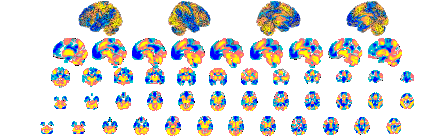

o2 = canlab_results_fmridisplay(get_wh_image(t, 2), 'montagetype', 'full', 'noverbose');

% TODO: FIXout_parcel = robfit_parcelwise(con_data_obj); %'names', ## );
